# FITELLIPSE : Least squares ellipse fitting demonstration

Richard Brown, May 28, 2007

## Introduction

This submission is based largely on the paper "Least-Squares Fitting of Circles and Ellipses", W. Gander, G. H. Golub, R. Strebel, BIT Numerical Mathematics, Springer 1994, and provides methods of fitting ellipses based on minimising algebraic distance (linear least squares) and geometric distance (nonlinear least squares)

## Linear least squares ellipse fitting - minimising algebraic distance

Least squares fitting of ellipses is a deceptively tricky task. Let's begin by specifying a general equation for an ellipse in 2D


$$F(\mathbf{x}) = \mathbf{x}^T A \mathbf{x} + \mathbf{b}^T \mathbf{x} + c = 0$$


where A is a 2x2 matrix, **x** = `[x; y]`. For more than 5 data points, and an appropriate constraint this is an overdetermined linear system, and a least squares solution minimising the algebraic distance 


$$\Sigma F(\mathbf{x})^2$$


can be found by linear least squares. Different choices of constraint will create different ellipse fits. It is desirable to choose a constraint on the parameters that is invariant under Euclidean transformations, so that you will get the same ellipse fit no matter where the point set is located in the plane. It turns out that any function of the eigenvalues of A is an appropriate such constraint. There are a number of different posibilities, e.g. FEX no. 7012 uses the constraint:


$$\textrm{det}(A) = \lambda_1 \lambda_2 = 1$$


Bookstein (1979) suggested the constraint


$$\lambda_1^2 + \lambda_2^2 = 1$$


And Gander, Golub, and Strebel (1994) suggested


$$\textrm{Trace}(A) = \lambda_1 + \lambda_2 = 1$$


All of which produce linear least squares systems. `fitellipse` implements the latter two as options `'bookstein'` and `'trace'` for the `'constraint'` property, with `'bookstein'` as default. `'plotellipse'` can be used to plot the fitted ellipses. We can have a look at the effect of the different constraints as follows:

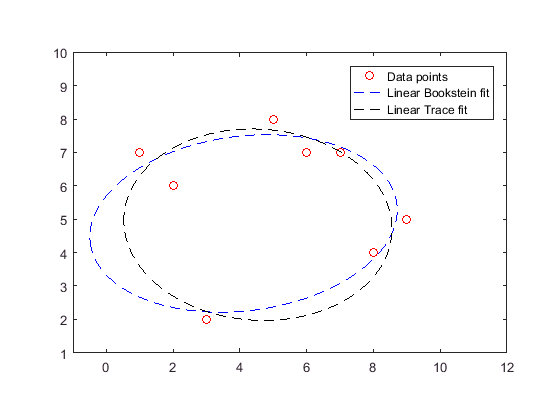

% A set of points
warning off;
x = [1 2 5 7 9 6 3 8; 
     7 6 8 7 5 7 2 4];
 
% Fit an ellipse using the Bookstein constraint
[zb, ab, bb, alphab] = fitellipse(x, 'linear');

% Fit an ellipse using the Trace constraint
[zt, at, bt, alphat] = fitellipse(x, 'linear', 'constraint', 'trace');

% Plot the results
plot(x(1,:), x(2,:), 'ro')
hold on
axis equal
axis([-1 12 1 10])
plotellipse(zb, ab, bb, alphab, 'b--')
plotellipse(zt, at, bt, alphat, 'k--')
legend('Data points', 'Linear Bookstein fit', 'Linear Trace fit')

## Nonlinear ellipse fitting - minising geometric distance

The above methods do not minimise the geometric error i.e. the Euclidean distance of the data points to the fitted ellipse, and as such can produce some undesirable results. The problem is that minising geometric error by least squares is a nonlinear least squares problem, and requires an iterative method to solve it as there is no closed form solution.

`fitellipse` provides a Gauss-Newton implementation which minimises geometric error. This can be used as follows:

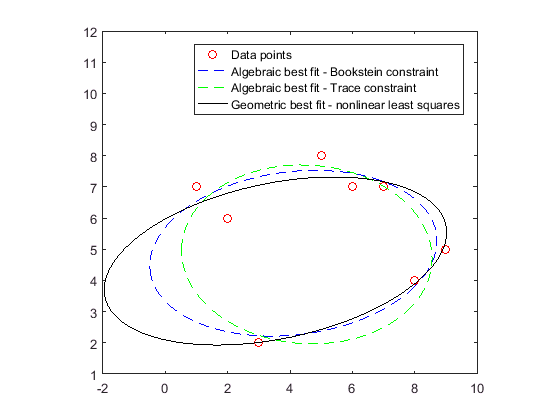

clf
[zg, ag, bg, alphag] = fitellipse(x);
plot(x(1,:), x(2,:), 'ro')
hold on
axis equal
axis([-2 10 1 12])
plotellipse(zb, ab, bb, alphab, 'b--')
plotellipse(zt, at, bt, alphat, 'g--')
plotellipse(zg, ag, bg, alphag, 'k')
legend('Data points', 'Algebraic best fit - Bookstein constraint', ...
    'Algebraic best fit - Trace constraint', ...
    'Geometric best fit - nonlinear least squares')

## Caveat - fitting circles

There is one potential problem with the Gauss Newton implementation employed here. If the ellipse is in fact a circle, and a == b, then the Jacobian matrix will be rank-deficient and the method may break down. This could be mitigated by switching to a more involved least squares method such as Levenberg-Marquardt, however I don't have the time or inclination to implement this myself, and I have stayed intentionally clear of using `lsqnonlin` as this requires the optimisation toolbox. 

Most of the time this won't affect you, but if it does you can use either one of the linear estimates `fitellipse(x, 'linear')` as discussed above, or a circle fitting routine e.g. `fitcircle`  [http://www.mathworks.com/matlabcentral/fileexchange/loadFile.do?objectId=15060&objectType=file](http://www.mathworks.com/matlabcentral/fileexchange/loadFile.do?objectId=15060&objectType=file)

## References

- FEX 7012: "Stable Direct Least Squares Fit of Ellipses", [http://www.mathworks.com/matlabcentral/fileexchange/loadFile.do?objectId=7012&objectType=FILE](http://www.mathworks.com/matlabcentral/fileexchange/loadFile.do?objectId=7012&objectType=FILE)

- Bookstein (1979) "Fitting Conic Sections to Scattered Data', F.L. Bookstein, Computer Graphics and Image Processing (1979) pp. 56-71